**TALLER EVALUATIVO 4**

**DANA CAROLINA CORONEL JIMENEZ**

ECUACIONES DIFERENCIALES

**MODELO DE UN PÉNDULO SIMPLE**

PROFESORA OLGA LUCIA MONTOYA

NOVIEMBRE, 2023

**Objetivo**

Resolver numéricamente la ecuación de estado no lineal de un péndulo simple en un archivo Live Script de MATLAB e interpretar los resultados cambiando diversos parámetros a partir de la respuesta temporal y retrato de fase.

**Descripción:**

Dada la siguiente la siguiente ecuación de estado de segundo orden no lineal de un modelo de un péndulo simple con fuerza tangencial, resolverla utilizando el método numérico de Runge-Kutta implementado en la función ode45 de MATLAB. 

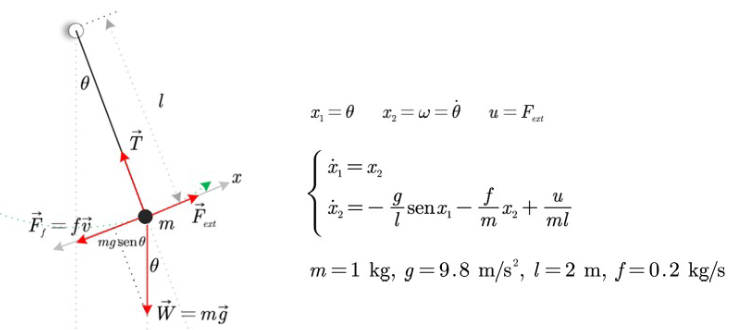

Donde, θ es el ángulo (en radianes, rad) respecto a la posición vertical, ω es la velocidad angular (en radianes por segundo, rad/s) y u es la fuerza externa aplicada tangencialmente. Los parámetros son la masa ( m, en kilogramos), la longitud (l, en metros), la aceleración de la gravedad (g, en m/s2) y f es el coeficiente de fricción viscosa (f, N/(ms-1) o kg/s).

Suposición: el hilo es rígido y tiene una masa que se puede despreciar, por lo que el péndulo puede tomar posiciones superiores.

**Punto 1**

Resolver numéricamente la ecuación diferencial no lineal y graficar las soluciones temporales con una entrada u = 1. ¿Para que valor máximo de la entrada el sistema rotará indefinidamente?

*a) Encontrar la solución numérica inicial cuando u=1*

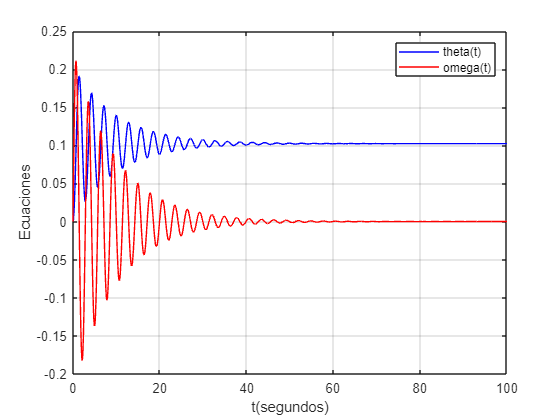

%Definición de las variables de estado x1=theta, x2=omega
syms x1(t) x2(t)

%Definición de parámetros
m = 1; 
g=9.8; 
l=2; 
f=0.2; 
u=1;

%Estableciendo las ecuaciones 
f1= x2;
f2= -(g/l)*sin(x1)-(f/m)*x2+(u/(m*l));

%Parte derecha de la ecuación de estado de forma numérica
f = odeFunction([f1 f2 ],[x1 x2]);

%Método numérico

%Definición del paso
h=0.1; 

%Definición del tiempo mínimo
tmin=0;

%Definición del tiempo máximo
tmax = 100; 

%Definición del intervalo de tiempo
tspan = 0:h:100; 

%Definición de condición inicial
ci=[0 0]; 

%Solución de la ecuación usando el método de Runge-Kutta
[t1,sol1] = ode45(f,tspan,ci);

theta=sol1(:,1);
omega=sol1(:,2);

%Graficando
plot(t1,theta,'b',t1,omega,'r') 

%Nombrando los ejes
xlabel('t(segundos)') 
ylabel('Ecuaciones') 
grid on 
legend({'theta(t)','omega(t)'})

¿Para que valor máximo de la entrada el sistema rotará indefinidamente?

*b) Encontrar la solución numérica inicial cuando u=7.55*

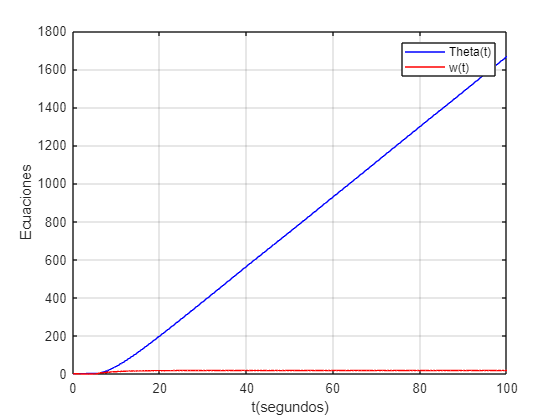

syms x1(t) x2(t) %Definir las variables de estado x1=theta, x2=omega

%Definiendo los parámetros
m = 1; 
g=9.8; 
l=2; 
f=0.2; 
u=7.55; 

%Estableciendo las ecuaciones 
f1= x2;
f2= -(g/l)*sin(x1)-(f/m)*x2+(u/(m*l));

%Parte derecha de la ecuación de estado de forma numérica
f = odeFunction([f1 f2],[x1 x2]);

%Método númerico

%Definición del paso
h=0.1; 

%Definición del intervalo de tiempo
tspan = 0:h:100; 

%Condición inicial
ci=[0 0]; 

%Solución de la ecuación usando el método de Runge-Kutta
[t1,sol1] = ode45(f,tspan,ci);

theta=sol1(:,1);
omega=sol1(:,2);

%Graficando
plot(t1,theta,'b',t1,omega,'r') 
xlabel('t(segundos)') 
ylabel('Ecuaciones') 
grid on 
legend({'Theta(t)','w(t)'}) 

hold off

**Análisis**

Para el péndulo en función del valor de u, define una variable que representa la amplitud de la fuerza de entrada. Cuando u es pequeño, el péndulo oscila alrededor de su posición de equilibrio, pero cuando es grande, el péndulo puede rotar indefinidamente. Para un valor específico de u (7.5), el péndulo se aproximará a una recta, y para valores aún mayores, se rotará indefinidamente. 

**Punto 2**

Trazar la curva de linealidad, es decir, el valor en el que se estabiliza el péndulo en función del valor de la entrada. El rango de entradas no debe superar el valor máximo calculado anteriormente.

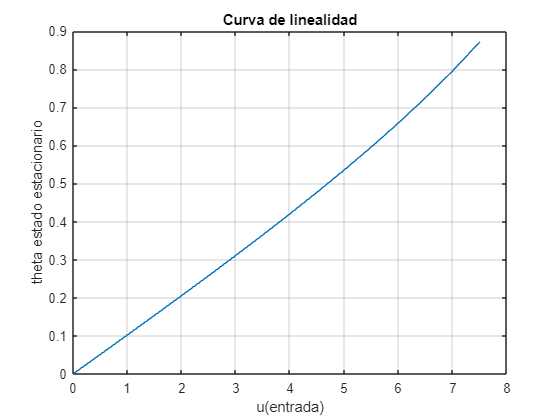

%Variables de estado: x1= theta, x2= omega

%Definición de parámetros 
m=1;
g=9.8;
L=2;
f=0.2;

%Estableciendo la ecuación
f1= x2;

%Definición del intervalo de tiempo
tspan= 0:0.01:100; 

%Definición de condiciones iniciales
ci= [0 0];

%Cálculo del valor en el que se estabiliza cada respuesta temporal para cada valor de la entrada
u1= 0:0.5:7.5;
N= length(u1);
thetass= zeros(1,N);

figure
for i= 1:N
    syms x1(t) x2(t)

    u= u1(i);
    f2= -(g/L)*sin(x1) - (f/m)*x2 + u/(m*L); fun= odeFunction([f1 f2],[x1 x2]); [t,x]= ode45(fun, tspan, ci); theta= x(:,1); thetass(i)= theta(end);
end


%Graficando
plot(u1, thetass) 
xlabel('u(entrada)')
ylabel('theta estado estacionario')
title('Curva de linealidad')
grid

hold off

**Análisis**

El sistema del péndulo que oscila en un rango de 1 a 8, donde valor máximo del rango es 8 y que a demás se puede deducir que el péndulo se estabiliza en el punto p=7.5, dejando de tener un crecimiento lineal como se expresa en la gráfica. El ángulo en el que se estabiliza el péndulo depende de la longitud de la cuerda, la masa del objeto que cuelga y la gravedad. En un péndulo simple ideal sin rozamiento, el ángulo en el que se estabiliza el péndulo en función de una entrada u=1 es de 0 grados, siempre y cuando la oscilación no sea demasiado grande y la cuerda no se estire demasiado.

**Punto 3**

Dibujar el retrato de fase para un cambio en la condición inicial de la velocidad angular entre 3 y 6 rad/s con incrementos de 0.5 rad/s. Interpretar el resultado. ¿Para qué valor de la frecuencia angular inicial el péndulo da una vuelta? ¿Para qué valor da tres vueltas? Observar los puntos de equilibrio.

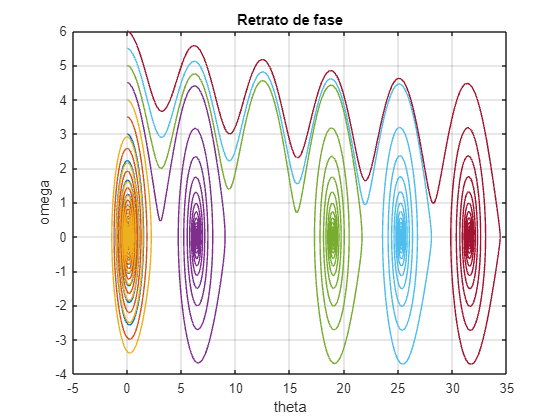

%Variables de estado: x1= teta, x2= omega

%Definición de parámetros
m=1;
g=9.8;
L=2;
f=0.2;
u= 1;
omega0= 3:0.5:6;

N=length(omega0);

figure
for i= 1:N

    %Definiendo variables
    syms x1(t) x2(t)

    f1= x2;
f2= -(g/L)*sin(x1) - (f/m)*x2 + u/(m*L); 
fun= odeFunction([f1 f2],[x1 x2]); 

%Definición del paso
h=0.01;

%Intervalo de tiempo (mínimo y máximo)
tspan= 0:h:100; 

%Condiciones iniciales
    ci= [0 omega0(i)];


    %Solución de la ecuación 
    [t,x]= ode45(fun, tspan, ci); 

    theta= x(:,1);
    omega= x(:,2);


%Graficando
    plot(theta, omega)
    hold on

end

    xlabel('theta')
    ylabel('omega')
    grid
    title('Retrato de fase')

    hold off

**Análisis**

A partir del retrato de fase y con el cambio de velocidad mencionado cuando u=1, el péndulo comienza a girar, y después de cada 2*pi*u, da una vuelta. En los puntos donde se produce el giro, se encuentran los puntos de equilibrio. Para que el péndulo complete una vuelta, el ángulo debe aumentar en 2*pi radianes para que el péndulo de una vuelta completa. De manera similar, para que el péndulo dé tres vueltas completas, la frecuencia angular inicial debe aumentar. Se puede definir que para que el péndulo de una vuelta completa theta debe aumentar.

**Punto 4**

Dibujar el retrato de fase para un cambio en la condición inicial de la posición angular entre -6 y 6 rad con incrementos de 0.5 rad. Interpretar el resultado. Observar los tres únicos puntos de equilibrio.

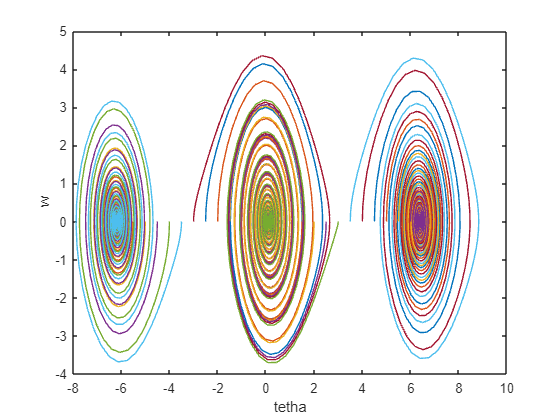

%Definición del paso
h=0.1;

%Definición del tiempo mínimo
tmin=0;

%Definición del tiempo máximo
tmax = 300;

%Intervalo de tiempo
tspan = 0:h:tmax;

%Definición de parámetros
m = 1; g=9.8; l=2; f=0.2;
tetha0 = -6:0.5:6;
u = 1;

for i=1:numel(tetha0)

    %Definición de variables
    syms x1(t) x2(t) 

    %Definición de las ecuaciones
    f1= x2; 
    f2=-(g/l)*sin(x1)-(f/m)*x2+(u/(m*l));

    %Parte derecha de la ecuación
    solucion = odeFunction([f1 f2],[x1 x2]);

    %Definir la condición inicial
    ci=[tetha0(i) 0]; 
    [t , x]=ode45(solucion,tspan,ci);
    tetha1= x(:,1);
    w = x(:,2);

%Graficando
plot(tetha1,w)
hold on
xlabel('tetha')
ylabel('w')

end

hold off

**Análisis**

El retrato de fase, donde se muestra de forma gráfica cómo cambia la posición y velocidad de un péndulo simple con el tiempo, con la posición angular entre -6 y 6 rad. Para hacer esta gráfica, se resuelve una ecuación matemática para diferentes valores iniciales de la posición y velocidad angular, y se dibuja la solución en una gráfica. Se Pueden observar  puntos de equilibrio en los que la posición y velocidad no cambian con el tiempo, siendo -pi, o y pi. Al graficar las soluciones para diferentes valores iniciales de la posición angular, se puede ver que todas convergen hacia uno de los tres puntos de equilibrio. Para valores iniciales negativos, las soluciones coinciden co que van hacia un punto, para valores iniciales positivos, hacia otro punto, y para la posición inicial cero, la solución permanece en el tercer punto de equilibrio.

**Punto 5**

Explicar el efecto del cambio de la longitud del péndulo en el desplazamiento angular (θ) con u = 1 y condiciones iniciales iguales a cero.0.

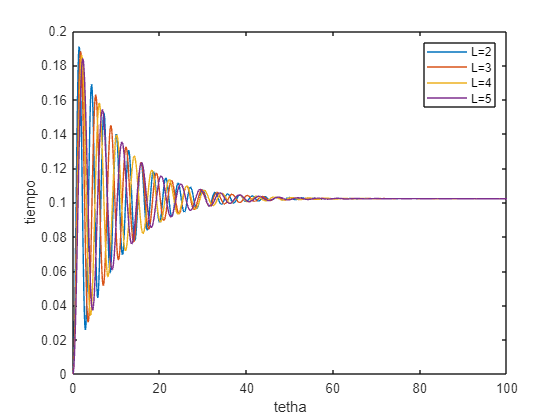

%Variables de estado: x1= teta, x2= omega

%Definición del paso
h=0.1;

%Definición del tiempo mínimo
tmin=0;

%Definición del tiempo máximo
tmax = 100;

%Intervalo de tiempo
tspan = 0:h:tmax;
m = 1; g=9.8; 

%Cambio de longitud de 2 a 5 con incrementos de 1
l=2:1:5; 

f=0.2;
u = 1;

for i=1:numel(l)

    %Definición de variables
    syms x1(t) x2(t) 
    f1= x2; 
    f2=-(g/l(i))*sin(x1)-(f/m)*x2+(u/(m*l(i)));
    solucion = odeFunction([f1 f2],[x1 x2]);

    %Definición de la condición inicial
    ci=[0 0]; 

    %Solución de la ecuación
    [t , x]=ode45(solucion,tspan,ci);
    tetha1= x(:,1);

%Graficando
plot(t,tetha1)
hold on
xlabel('tetha')
ylabel('tiempo')
end
legend({'L=2','L=3','L=4','L=5'})

hold off

**Análisis**

El desplazamiento angular (θ) del péndulo está directamente relacionado con la longitud del mismo, es por esto que cuando la longitud del péndulo se modifica, el desplazamiento angular también cambia. Teniendo en cuenta que las condiciones iguales fueron iguales a 0 y que se tiene que u=1 se puede deducir que al aumentar la longitud del péndulo, este tardará más tiempo en completar la ida y vuelta. Eso significa que el desplazamiento angular (θ) también será mayor, pues el péndulo tiene más tiempo para moverse de un lado a otro. Por el contrario, si se reduce la longitud de este, tardará menos tiempo en completar un ciclo completo de ida y vuelta. Eso significa que el desplazamiento angular (θ) también será menor, porque el péndulo tendrá menos tiempo para moverse hacia la izquierda y hacia la derecha.

**Punto 6**

Explicar el efecto del cambio de la masa del péndulo en el desplazamiento angular (θ) con u = 1 y condiciones iniciales iguales a cero.

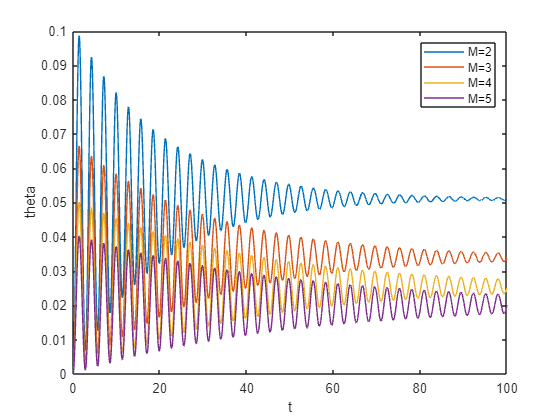

%Variables de estado: x1= teta, x2= omega

%Definición de parametros

%Cambiando los valores de m
m=2:1:5;
g=9.8;
L=2;
f=0.2;
u= 1;

N = numel(m);

for i= 1:N

    %Definición de variables
    syms x1(t) x2(t)
     
    %Definición de ecuaciones
    f1= x2;
   f2= -(g/L)*sin(x1) - (f/m(i))*x2 + u/(m(i)*L); 
   fun= odeFunction([f1 f2],[x1 x2]); 

  %Definición del intervalo de tiempo
  tspan= 0:0.01:100;

    %Definición de condiciones iniciales
    ci= [0 0];
    [t,x]= ode45(fun, tspan, ci); 
    theta= x(:,1);
   

    %Graficando
    plot(t,theta)
    hold on
    xlabel('t')
    ylabel('theta')
    grid 

end

legend({'M=2','M=3','M=4','M=5'})
 hold off

**Análisis **

El movimiento del péndulo depende de su longitud, de la gravedad del lugar y de su masa. Si se mantienen constantes la longitud del péndulo y la aceleración gravitatoria, entonces la variación de la masa del péndulo afectará el desplazamiento angular (θ). Esto se debe a que la energía total del sistema aumentaría si solo cambia la masa del péndulo.

**Punto 7**

Explicar el efecto del cambio de la fricción viscosa del péndulo en el desplazamiento angular (θ) con u = 1 y condiciones iniciales iguales a cero.

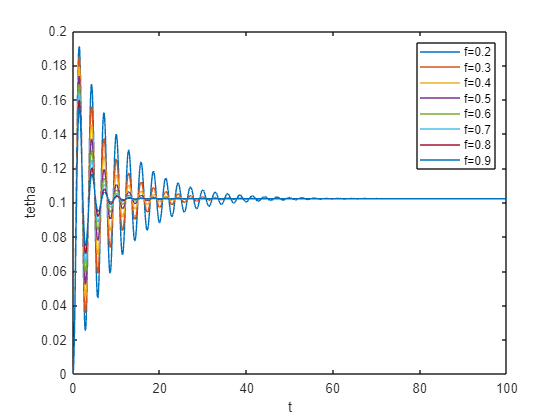

%Variables de estado: x1= teta, x2= omega

%Definición de parametros
m=1;
g=9.8;
L=2;

%Cambiando los valores de f
f=0.2:0.1:0.9;
u= 1;

N = numel(f);

for i= 1:N

    %Definición de variables
    syms x1(t) x2(t)

    f1= x2;
   f2= -(g/L)*sin(x1) - (f(i)/m)*x2 + u/(m*L); 
  fun= odeFunction([f1 f2],[x1 x2]); 

  %Intervalo de tiempo
  tspan= 0:0.01:100; 

   %Condiciones iniciales
    ci= [0 0];
    [t,x]= ode45(fun, tspan, ci); 
    theta= x(:,1);
   
    %Graficando
    plot(t,theta)
    hold on
    xlabel('t')
    ylabel('tetha')
    grid  

end

legend({'f=0.2','f=0.3','f=0.4','f=0.5','f=0.6','f=0.7','f=0.8','f=0.9'})

    hold off

**Análisis**

La fricción viscosa del péndulo afecta su velocidad y desplazamiento angular, sus cambios se dan en cada periodo de giro como s evidencia en la gráfica. Es por esto que si la fricción viscosa aumenta, la velocidad angular disminuirá y el desplazamiento angular(θ) será menos pronunciado, mientras que si se reduce la fricción viscosa, la velocidad angular aumentará y el desplazamiento angular será más pronunciado. En otras palabras, la fricción viscosa influye en la forma en que el péndulo se mueve y puede afectar directamente en los resultados de análisis.

**Punto 8**

Si f = 0, u = 0 (movimiento libre no amortiguado) y la posición angular inicial ω(0) es menor a unos 30° (0.5 radianes, aproximadamente), se puede aproximar el seno del ángulo en radianes por el ángulo (comprobar con la calculadora o MATLAB) y el modelo es lineal. Obtener la ecuación de estado, pasar a la ecuación diferencial homogénea con coeficientes constantes y resolverla analíticamente. ¿Cómo se puede medir la aceleración de la gravedad si se conoce la longitud? ¿Cómo se puede obtener la longitud si se conoce la aceleración de la gravedad? 

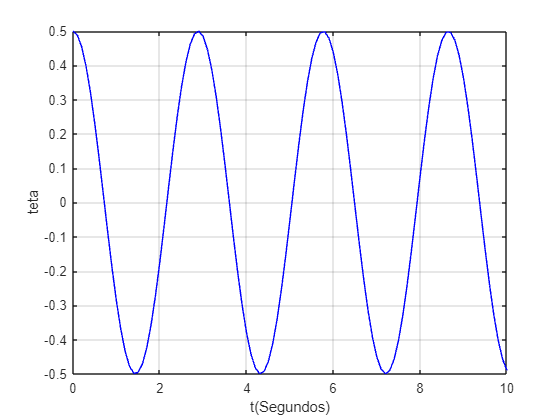

syms x1(t) x2(t) %Definimos las variables simbólicas

%Establecemos los parámetros
m=1; 
g=9.8; 
l=2; 
f=0; 
u=0; 

%Definición de las ecuaciones
F1= x2; 
F2= -(g/l)*sin(x1)-(f/m)*x2+(u/(m*l)); 
F = odeFunction([F1 F2],[x1 x2]);

%Definición del método numérico

%Definición del paso
h=0.1; 

%Definición del tiempo mínimo
tmin=0; 

%Definición del tiempo máximo
tmax = 10; 

%Intervalo de tiempo
tspan = tmin:h:tmax; 

%Condición inicial
ci=[0.5 0]; 

%Solución por el método de Runge-Kutta
[t1,sol1] = ode45(F,tspan,ci);

Teta=sol1(:,1); 

% Graficando
plot(t1,Teta,'b') 
xlabel('t(Segundos)') 
ylabel('teta') 
grid on 

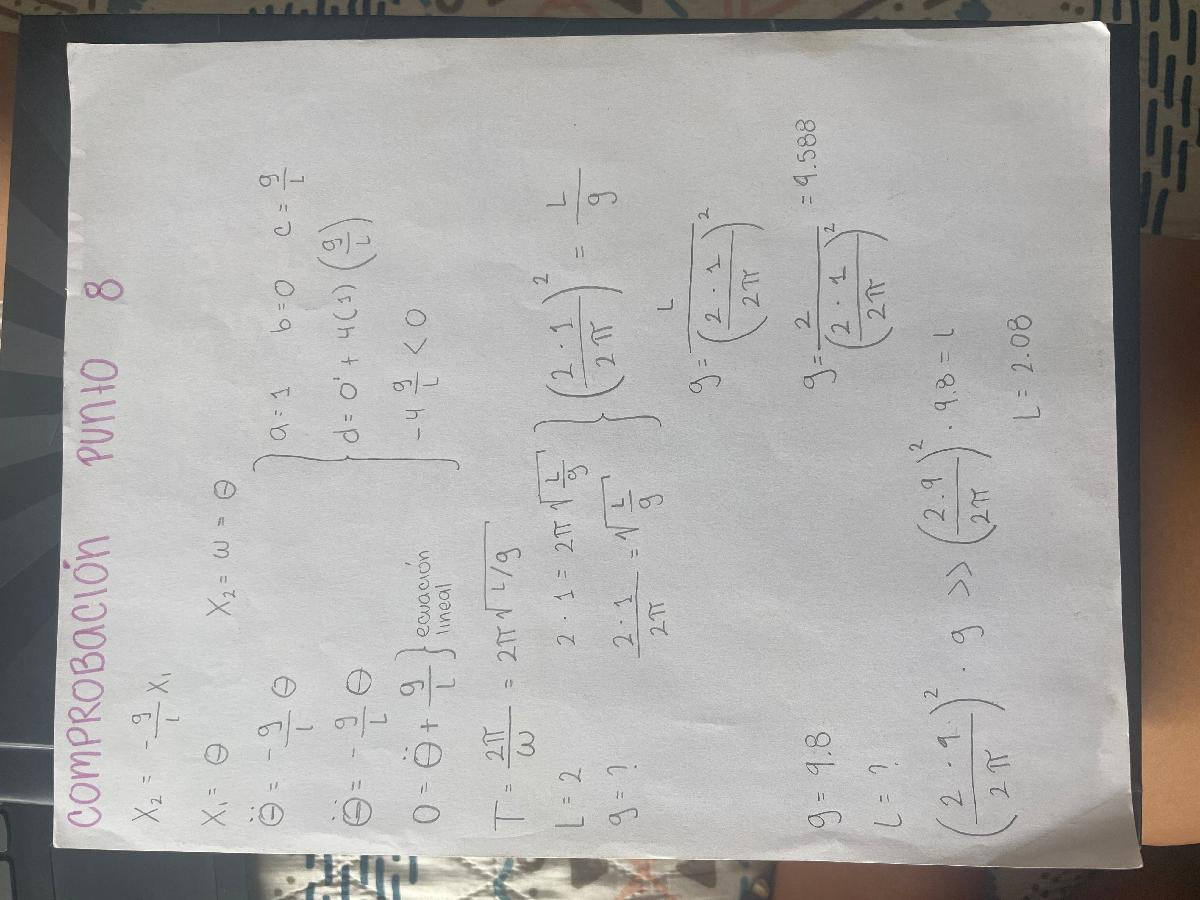

**Análisis**

Para hallar la gravedad y la longitud pedidas en este punto se debe conocer el período, que se puede obtener de la gráfica, en este caso 2.9. Luego, se utilizan las ecuaciones de estado y la ecuación lineal de segundo orden para despejar la aceleración de la gravedad. Sabiendo que la longitud es de 2, se obtiene una aceleración de 9.388. Para obtener la longitud, se despeja la ecuación sabiendo que la gravedad es de 9.88, lo que da una longitud de 2.08. Los valores obtenidos son aproximados. La gráfica muestra que el péndulo oscila con la misma amplitud durante todo el tiempo y no se estabiliza debido a que no hay fuerzas externas ni coeficiente de fricción en el sistema que afecten su oscilación.

**Punto 9**

Si se conoce la respuesta temporal de un péndulo con fuerza igual a 1 N, l = 2 y g = 9.8, hallar aproximadamente por tanteo los valores de f y m. Explicar el procedimiento. Tener en cuenta los resultados de las tareas 6 y 7.

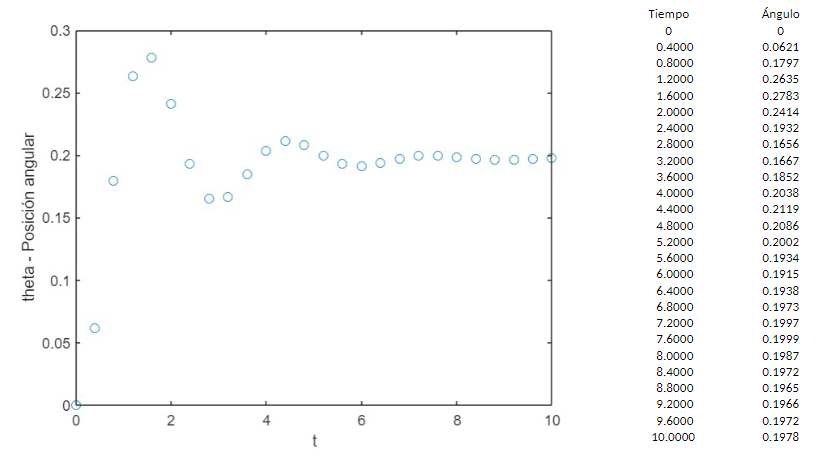

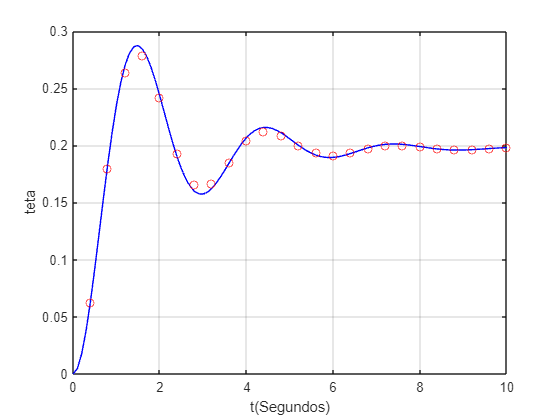

tiempo = [0.4000 0.8000 1.2000 1.6000 2.0000 2.4000 2.8000 3.2000 3.6000 4.0000 4.4000 4.8000 5.2000 5.6000 6.0000 6.4000 6.8000 7.2000 7.6000 8.0000 8.4000 8.8000 9.2000 9.6000 10.0000];
angulo = [0.0621 0.1797 0.2635 0.2783 0.2414 0.1932 0.1656 0.1667 0.1852 0.2038 0.2119 0.2086 0.2002 0.1934 0.1915 0.1938 0.1973 0.1997 0.1999 0.1987 0.1972 0.1965 0.1966 0.1972 0.1978];

%Definición de variables
syms x1(t) x2(t) 

%Definición de los parámetros

%Iterando para hallar m
m=0.52; 
g=9.8; 
l=2; 

%Iterando para hallar f
f=0.56; 
u=1; 

%Definición de ecuaciones
F1= x2; 
F2= -(g/l)*sin(x1)-(f/m)*x2+(u/(m*l)); 
F = odeFunction([F1 F2],[x1 x2]);

%Definición del método numérico

% Definición del paso
h=0.1; 

%Definición del tiempo mínimo
tmin=0; 

%Definición del tiempo máximo
tmax = 10; 

%Intervalo de tiempo
tspan = tmin:h:tmax; 

%Definición de condició inicial
ci=[0 0]; 

%Solución por el método de Runge-Kutta
[t1,sol1] = ode45(F,tspan,ci);

Teta=sol1(:,1);

% Graficando
plot(t1,Teta,'b') 
hold on
plot(tiempo,angulo,'ro')
xlabel('t(Segundos)') 
ylabel('teta') 
grid on 
hold off

**Análisis**

En este ejercicio el análisis se basa en la gráfica resultante, que determina logra hallar los valores de f y m po rtanteo, se hicieron varias iteraciones hasta que se logró llegar a un resultado que coincidía casi en su mayoría con los nodos. Estas iteraciones se basaron en los resultados encontrados en las gráficas del punto 6 para halalr m y del punto 7 para hallar f. Dando como resultados que f=0.56 y m=0.52